## **Assignment 3 Smart Throttle:Control Techniques Beyond Basic PID**

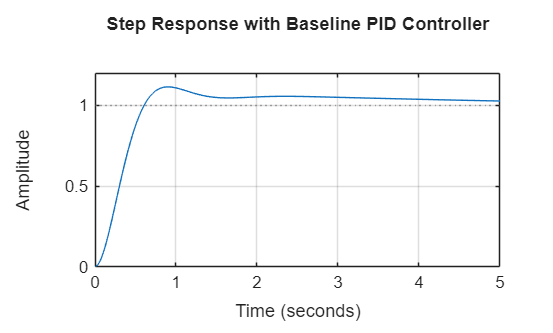

%Problem1)a)Baseline PID performance

s = tf('s');

% Given plant
G = 20 / ( s*(s+2)*(s+5) );
%PID tuning
C_PID = pidtune(G,'PID');

%% Closed-loop System with PID

T_PID = feedback(C_PID * G, 1);

% Step response
figure;
step(T_PID, 5);
grid on;
title('Step Response with Baseline PID Controller');

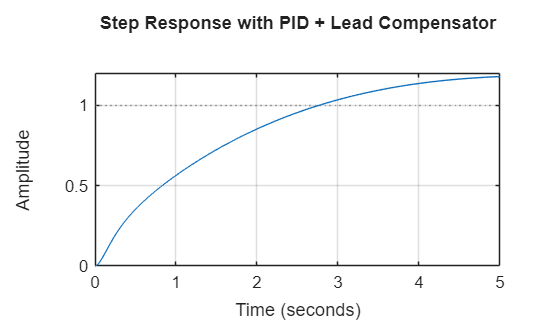

%Performance Metrics
info_PID = stepinfo(T_PID);

%Problem1)b)Lead Compensator Design

z = 3;
p = 15;
Kc = 1;   

C_lead = Kc * (s + z) / (s + p);
% Combined Controller

C_total = C_PID * C_lead;

T_total = feedback(C_total * G, 1);

figure;
step(T_total, 5);
grid on;
title('Step Response with PID + Lead Compensator');

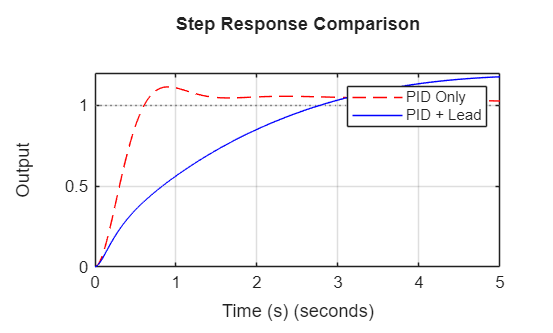

info_final = stepinfo(T_total);

%Problem1)c)Performance Comparison

figure;
step(T_PID,'r--',T_total,'b',5);
grid on;
legend('PID Only','PID + Lead');
title('Step Response Comparison');
xlabel('Time (s)');
ylabel('Output');

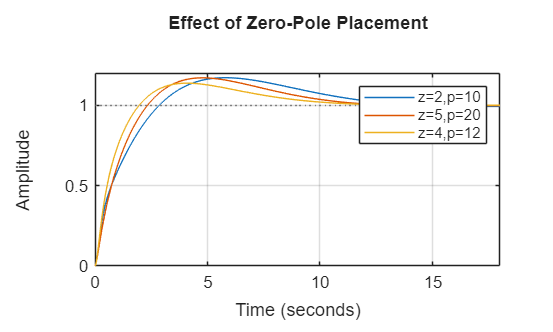


%Problem1)d)Parameter Experimentation:
params = [2 10; 5 20; 4 12];
figure; hold on;

for i = 1:size(params,1)
    z = params(i,1);
    p = params(i,2);
    C_lead = (s+z)/(s+p);
    T = feedback(C_PID*C_lead*G, 1);
    step(T);
end

grid on;
legend('z=2,p=10','z=5,p=20','z=4,p=12');
title('Effect of Zero-Pole Placement');

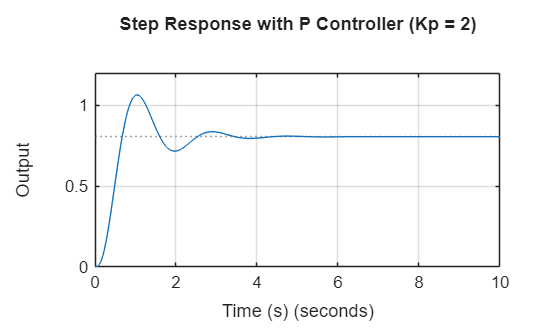



%Problem2)Lag Compensator for Steady-State Accuracy

s = tf('s');

% Given temperature control plant
G = 50 / ((s+1)*(s+3)*(s+8));
%% Proportional Controller (P Only)

Kp = 2;
C_P = Kp;

% Closed-loop system
T_P = feedback(C_P * G, 1);

figure;
step(T_P, 10);
grid on;
title('Step Response with P Controller (Kp = 2)');
xlabel('Time (s)');
ylabel('Output');


% Steady-State Error (P Only)

[y_P, t_P] = step(T_P, 10);
r_final = 1;                 % Unit step input
y_final_P = y_P(end);

ess_P = abs(r_final - y_final_P);

fprintf('Steady-State Error (P Controller only): %.4f\n', ess_P);

Steady-State Error (P Controller only): 0.1935


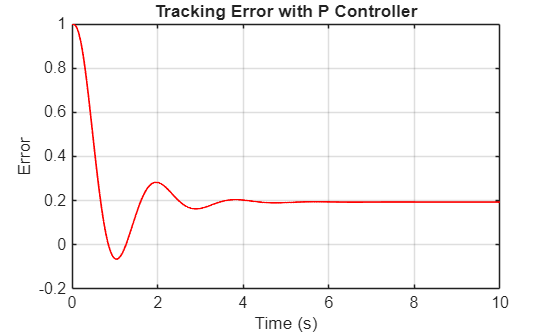


% Error Plot(P Only)

error_P = r_final - y_P;

figure;
plot(t_P, error_P, 'r','LineWidth',1);
grid on;
title('Tracking Error with P Controller');
xlabel('Time (s)');
ylabel('Error');

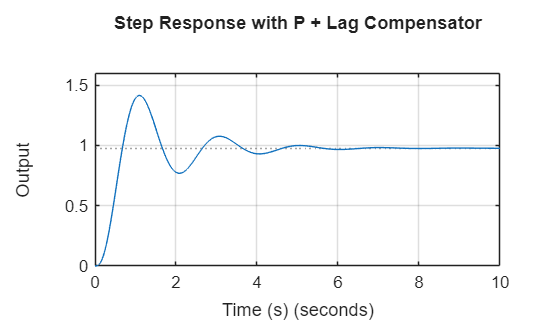


%problem2)b)
z = 1;
p = 0.1;
Kc = 1;

C_lag = Kc * (s + z) / (s + p);

% P + Lag Controller

C_total = C_P * C_lag;

T_lag = feedback(C_total * G, 1);

figure;
step(T_lag, 10);
grid on;
title('Step Response with P + Lag Compensator');
xlabel('Time (s)');
ylabel('Output');


%problem2)c)
% Steady-State Error (P + Lag)

[y_lag, t_lag] = step(T_lag, 10);
y_final_lag = y_lag(end);

ess_lag = abs(r_final - y_final_lag);

fprintf('Steady-State Error (P + Lag): %.4f\n', ess_lag);

Steady-State Error (P + Lag): 0.0240


% Settling Times

info_P   = stepinfo(T_P);
info_lag = stepinfo(T_lag);

Ts_P   = info_P.SettlingTime;
Ts_lag = info_lag.SettlingTime;

% Performance Comparison Table

Error_Reduction_Percent = ((ess_P - ess_lag)/ess_P)*100;

Comparison_Table = table( ...
    ess_P, ess_lag, Error_Reduction_Percent, Ts_P, Ts_lag, ...
    'VariableNames', { ...
    'SteadyStateError_P', ...
    'SteadyStateError_P_Lag', ...
    'ErrorReduction_Percent', ...
    'SettlingTime_P', ...
    'SettlingTime_P_Lag'});

disp('Steady-State Performance Comparison:')

Steady-State Performance Comparison:


disp(Comparison_Table)

    SteadyStateError_P    SteadyStateError_P_Lag    ErrorReduction_Percent    SettlingTime_P    SettlingTime_P_Lag
    __________________    ______________________    ______________________    ______________    __________________

         0.19355                 0.023982                   87.609                3.2198              5.2126      



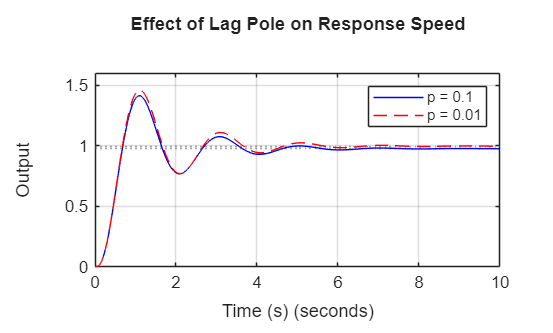

%Problem2)d)

p_new = 0.01;

C_lag_new = Kc * (s + z) / (s + p_new);
C_total_new = C_P * C_lag_new;

T_lag_new = feedback(C_total_new * G, 1);

figure;
step(T_lag,'b',T_lag_new,'r--',10);
grid on;
legend('p = 0.1','p = 0.01');
title('Effect of Lag Pole on Response Speed');
xlabel('Time (s)');
ylabel('Output');

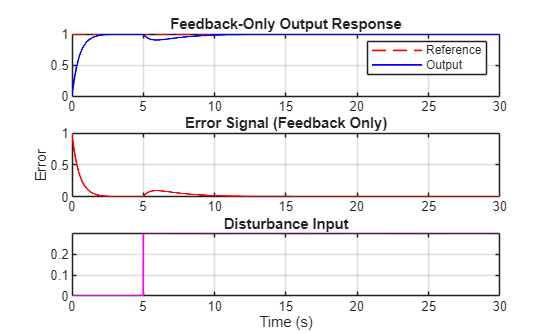


% Compare Trade-off Quantitatively

[y_new, ~] = step(T_lag_new, 10);
ess_new = abs(r_final - y_new(end));

info_new = stepinfo(T_lag_new);

%Problem 3)Feedforward + Feedback Control
s = tf('s');
G = 1 / (s + 0.5);

%% Simulation Setup

t = 0:0.01:30;        % Simulation time
r = ones(size(t));   % Reference speed (constant)

d = 0.3 * (t >= 5);  % step disturbance at t = 5s
%Problem3)a)
% Feedback-Only PI Controller

Kp = 2;
Ki = 1;
C_fb = Kp + Ki/s;
% Feedback-Only Closed Loop

% Closed-loop transfer function
T_fb = feedback(C_fb*G, 1);

% Response to reference
y_r_fb = lsim(T_fb, r, t);

% Disturbance effect
y_d_fb = lsim(G/(1 + C_fb*G), d, t);

% Total output
y_fb = y_r_fb - y_d_fb;
y_fb = y_fb(:);      % force column
r    = r(:);         % force column
e_fb = r - y_fb;     % now same length as t

% Feedback-Only Response Plots

figure;
subplot(3,1,1)
plot(t,r,'r--',t,y_fb,'b','LineWidth',1);
grid on;
legend('Reference','Output');
title('Feedback-Only Output Response');

subplot(3,1,2)
plot(t,e_fb,'r','LineWidth',1);
grid on;
title('Error Signal (Feedback Only)');
ylabel('Error');

subplot(3,1,3)
plot(t,d,'m','LineWidth',1);
grid on;
title('Disturbance Input');
xlabel('Time (s)');

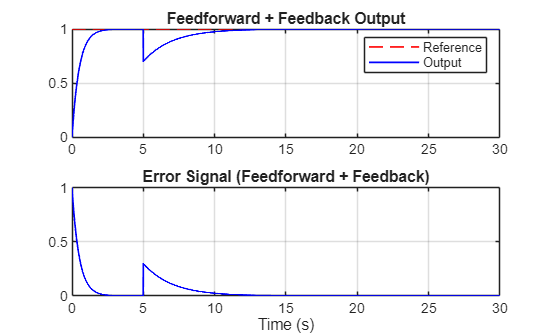



% Performance Metrics (Feedback Only)

[max_err_fb, idx_fb] = max(abs(e_fb));
t_peak_fb = t(idx_fb);

% Recovery time (error < 2%)
recovery_idx_fb = find(abs(e_fb) < 0.02, 1, 'last');

if isempty(recovery_idx_fb)
    recovery_time_fb = NaN;   % did not recover within tolerance
else
    recovery_time_fb = t(recovery_idx_fb);
end

Kff = 1 / dcgain(G);

t = t(:);
r = r(:);
d = d(:);

u_ff = Kff * d;
u_fb = lsim(C_fb/(1 + C_fb*G), r, t);
u_fb = u_fb(:);

u_total = u_fb + u_ff;
u_total = u_total(:);

y_ff = lsim(G, u_total, t) - d;
y_ff = y_ff(:);

e_ff = r - y_ff;

figure;
subplot(2,1,1)
plot(t,r,'r--',t,y_ff,'b','LineWidth',1);
grid on;
legend('Reference','Output');
title('Feedforward + Feedback Output');

subplot(2,1,2)
plot(t,e_ff,'b','LineWidth',1);
grid on;
title('Error Signal (Feedforward + Feedback)');
xlabel('Time (s)');

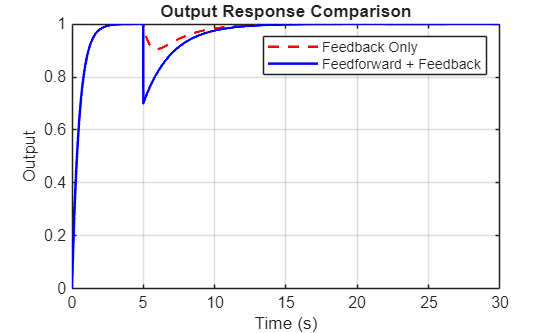


figure;
plot(t,y_fb,'r--',t,y_ff,'b','LineWidth',1.5);
grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Output Response Comparison');
xlabel('Time (s)');
ylabel('Output');

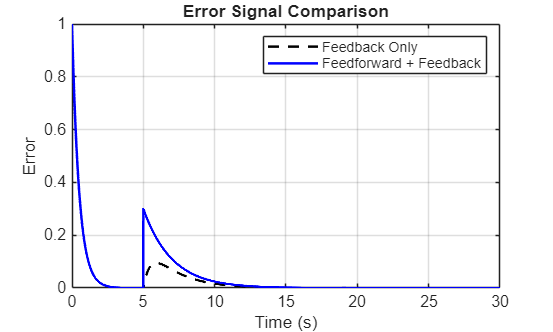


figure;
plot(t,e_fb,'k--',t,e_ff,'b','LineWidth',1.5);
grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Error Signal Comparison');
xlabel('Time (s)');
ylabel('Error');

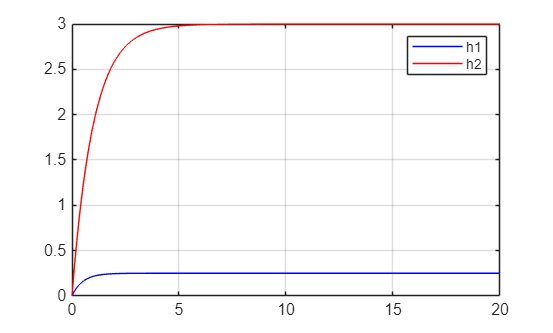


max_err_ff = max(abs(e_ff));
recovery_idx_ff = find(abs(e_ff) < 0.02, 1, 'last');

if isempty(recovery_idx_ff)
    recovery_time_ff = NaN;
else
    recovery_time_ff = t(recovery_idx_ff);
end

ess_fb = abs(e_fb(end));
ess_ff = abs(e_ff(end));

Performance_Table = table( ...
    max_err_fb, max_err_ff, ...
    recovery_time_fb, recovery_time_ff, ...
    ess_fb, ess_ff, ...
    'VariableNames', { ...
    'MaxError_FB','MaxError_FF', ...
    'RecoveryTime_FB','RecoveryTime_FF', ...
    'SteadyStateError_FB','SteadyStateError_FF'});


%Problem 4:Simple MIMO System Control
% problem 4(a)
G11 = tf(2,[1 1]);
G12 = tf(0.5,[1 2]);
G21 = tf(1,[1 1.5]);
G22 = tf(3,[1 1]);

G = [G11 G12; G21 G22];

t = (0:0.01:20)';

u1 = zeros(length(t),1);
u2 = ones(length(t),1);
u = [u1 u2];

[y,~] = lsim(G,u,t);

h1 = y(:,1);
h2 = y(:,2);

figure;
plot(t,h1,'b',t,h2,'r');
legend('h1','h2');
grid on;


Kp1 = 1.5; 
Ki1 = 0.8;
Kp2 = 1.2; 
Ki2 = 0.6;

h1_final = h1(end);
h2_final = h2(end);

info_h1 = stepinfo(h1,t);
info_h2 = stepinfo(h2,t);

settling_h1 = info_h1.SettlingTime;
settling_h2 = info_h2.SettlingTime;

Problem4_Table = table( ...
    ["Tank 1 Level (h1)"; "Tank 2 Level (h2)"], ...
    [h1_final; h2_final], ...
    [settling_h1; settling_h2], ...
    'VariableNames',{'Output','Final_Value','Settling_Time'});

Problem4_Table

Problem4_Table = 2×3 table
          Output           Final_Value    Settling_Time
    ___________________    ___________    _____________

    "Tank 1 Level (h1)"       0.25            1.956    
    "Tank 2 Level (h2)"          3            3.912    
